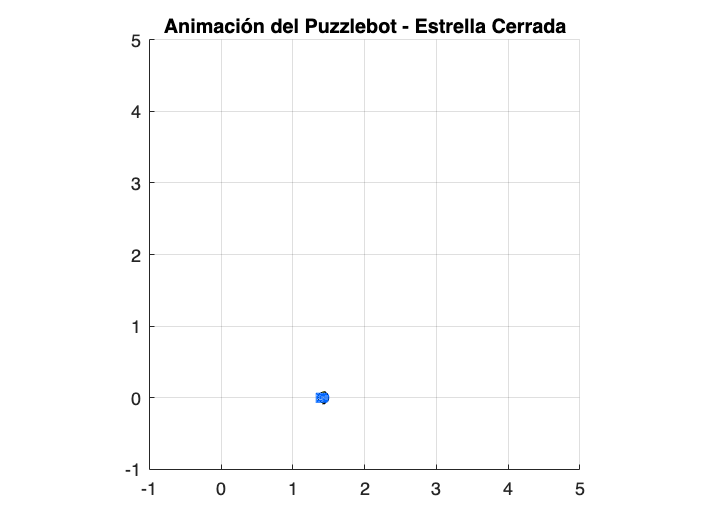

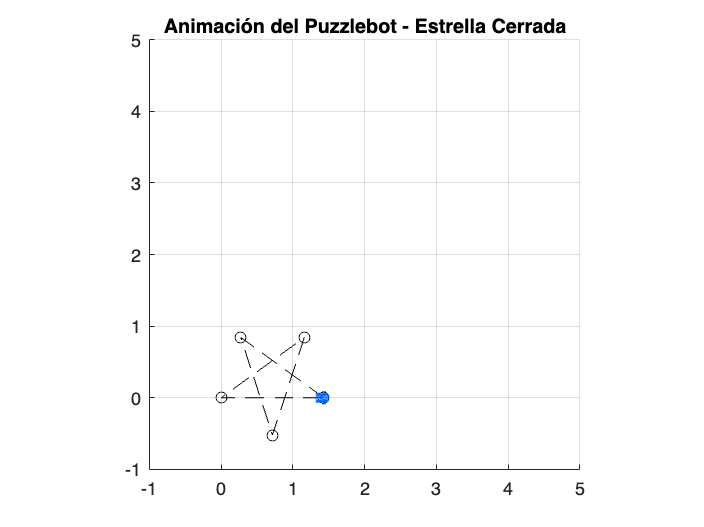

%Ejercicio 1

clear; clc;
global Uniciclo;

% Inicialización
x = 0; y = 0; theta = 0;

% Agregamos el último segmento recto para cerrar la estrella
v = [1.432, 0, 1.432, 0, 1.432, 0, 1.432, 0, 1.432, 0, 1.432];
w = [0, 2.513, 0, 2.513, 0, 2.513, 0, 2.513, 0, 2.513, 0];
dt = ones(1, length(v));
poses = zeros(length(v), 3);

% Cargar modelo 3D del robot
MobileRobot_5();

% Crear figura
figure;
hold on; grid on; axis equal;
xlim([-1 5]); ylim([-1 5]);
view(2);
title('Animación del Puzzlebot - Estrella Cerrada');

% Simulación y animación
for k = 1:length(v)
    % Cinemática
    x = x + v(k) * cos(theta) * dt(k);
    y = y + v(k) * sin(theta) * dt(k);
    theta = theta + w(k) * dt(k);
    poses(k, :) = [x, y, theta];

    % Animación
    cla;
    MobilePlot_4(x, y, theta, 1);           % Dibuja el robot
    plot(poses(1:k,1), poses(1:k,2), 'k--o'); % Traza la trayectoria
    pause(0.5);
end


% Mostrar tabla de resultados
T1 = table((1:length(v))', poses(:,1), poses(:,2), poses(:,3), ...
    'VariableNames', {'Paso', 'x', 'y', 'theta_rad'});
disp(T1);

    Paso         x              y         theta_rad
    ____    ___________    ___________    _________

      1           1.432              0          0  
      2           1.432              0      2.513  
      3         0.27372        0.84203      2.513  
      4         0.27372        0.84203      5.026  
      5         0.71548       -0.52013      5.026  
      6         0.71548       -0.52013      7.539  
      7          1.1591        0.84142      7.539  
      8          1.1591        0.84142     10.052  
      9     -0.00031834     0.00098158     10.052  
     10     -0.00031834     0.00098158     12.565  
     11          1.4317    -0.00098114     12.565  




% Mostrar pose final
p_final = poses(end, :);
fprintf('\nPose final:\n');


Pose final:


fprintf('x = %.2f m\ny = %.2f m\ntheta = %.2f rad | (%.0f°)\n', ...
    p_final(1), p_final(2), p_final(3), rad2deg(p_final(3)));

x = 1.43 m
y = -0.00 m
theta = 12.56 rad | (720°)


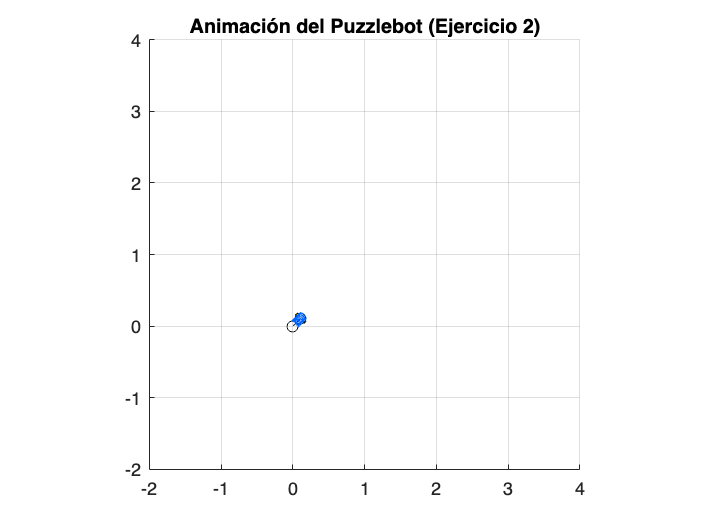

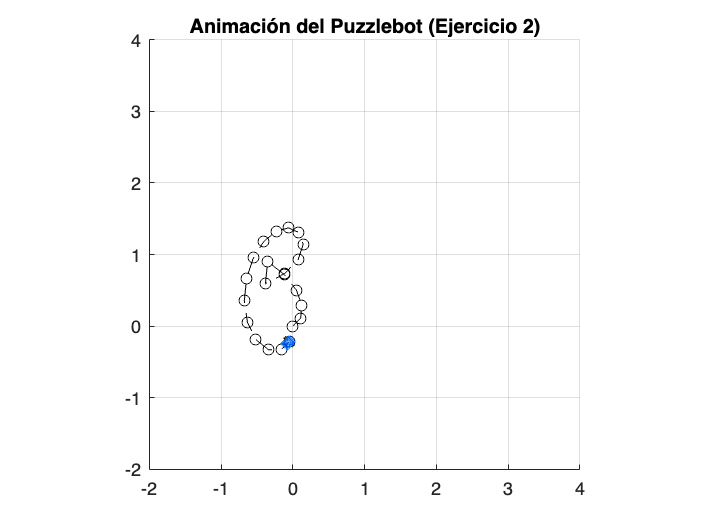

%Ejercicio 2

% Parámetros del robot
radio_rueda = 0.05;   % Radio de rueda (m)
L_eje = 0.18;         % Distancia entre ruedas (m)
dt2 = 1.0;            % Intervalo de tiempo (s)

omegaR = [4.582, 4.773, 5.291, 5.960, 6.490, ...
         -1.168, -1.364, 5.960, 5.291, 4.773, ...
          4.582, 4.773, 5.291, 5.960, 6.490, ...
          6.686, 6.490, 5.960, 5.291, 4.773, 4.582];

omegaL = [1.701, 2.353, 3.676, 4.856, 5.618, ...
         13.735, 13.472, 4.856, 3.676, 2.353, ...
          1.701, 2.353, 3.676, 4.856, 5.618, ...
          5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

N2 = length(omegaR);

% Inicialización de variables
vr = zeros(1, N2);
wr = zeros(1, N2);
xr = zeros(1, N2+1); yr = zeros(1, N2+1); thetar = zeros(1, N2+1);
xr(1) = 0; yr(1) = 0; thetar(1) = 0;

MobileRobot_5(); 

% Crear figura para animación
figure;
hold on; grid on; axis equal;
xlim([-2, 4]); ylim([-2, 4]);  % ajusta según la trayectoria
title('Animación del Puzzlebot (Ejercicio 2)');

% Simulación con animación
for k = 1:N2
    % Cinemática diferencial
    vr(k) = (radio_rueda / 2) * (omegaR(k) + omegaL(k));
    wr(k) = (radio_rueda / L_eje) * (omegaR(k) - omegaL(k));
    
    thetar(k+1) = thetar(k) + wr(k) * dt2;
    xr(k+1) = xr(k) + vr(k) * cos(thetar(k+1)) * dt2;
    yr(k+1) = yr(k) + vr(k) * sin(thetar(k+1)) * dt2;

    % Animación
    cla;
    MobilePlot_4(xr(k+1), yr(k+1), thetar(k+1), 1);  % Escala = 1
    plot(xr(1:k+1), yr(1:k+1), 'k--o');
    pause(0.4);  % Velocidad de animación
end


% Crear tabla de resultados
T2 = table((0:N2)', ...
    [vr, NaN]', ...
    [wr, NaN]', ...
    [omegaR, NaN]', ...
    [omegaL, NaN]', ...
    xr', yr', rad2deg(thetar)', ...
    'VariableNames',{'t(s)', 'v(m/s)', 'w(r/s)', ...
                             'w_R', 'w_L', ...
                             'x_m', 'y_m', 'theta (°)'});
disp(T2);

    t(s)    v(m/s)     w(r/s)      w_R       w_L         x_m         y_m        theta (°) 
    ____    _______    _______    ______    ______    _________    ________    ___________

      0     0.15707    0.80028     4.582     1.701            0           0              0
      1     0.17815    0.67222     4.773     2.353       0.1094     0.11271         45.853
      2     0.22418    0.44861     5.291     3.676      0.12689        0.29         84.368
      3      0.2704    0.30667      5.96     4.856     0.049952     0.50056         110.07
      4      0.3027    0.24222      6.49     5.618     -0.11519     0.71467         127.64
      5     0.31418    -4.1397    -1.168    13.735     -0.35215     0.90302         141.52

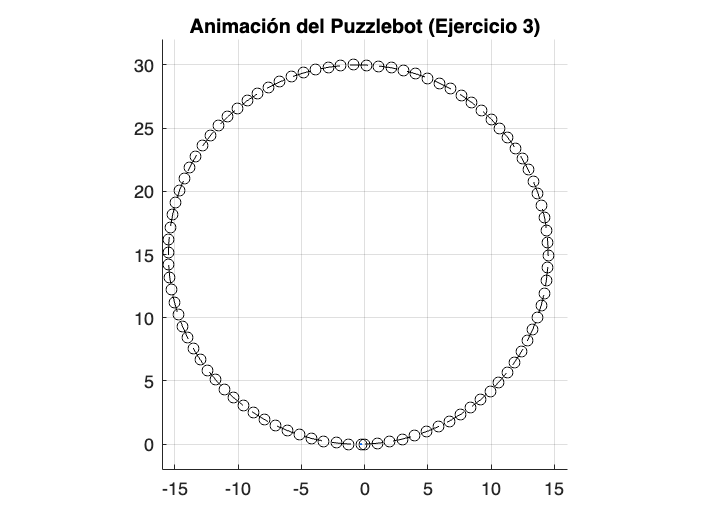

%Ejercicio 3

% Parámetros del robot
v = 1.0;      % Velocidad lineal (m/s)
r = 0.05;     % Radio de la rueda (m)
R = 15;       % Radio de trayectoria circular deseada (m)
L = 0.18;     % Distancia entre ruedas (m)
dt = 1.0;     % Tiempo entre pasos (s)

% Cálculo de velocidades angulares
w = v / R;
omegaR = (2*v + w*L) / (2*r);
omegaL = (2*v - w*L) / (2*r);

N = 94;  % Número de pasos

% Inicialización de variables
xr = zeros(1, N+1);
yr = zeros(1, N+1);
thetar = zeros(1, N+1);
vr = zeros(1, N);
wr = zeros(1, N);


MobileRobot_5();  

% Crear figura para animación
figure;
hold on; grid on; axis equal;
view(2);                     
xlim([-16, 16]); ylim([-2, 32]);
set(gca, 'ZLim', [-1 1]);      
title('Animación del Puzzlebot (Ejercicio 3)');

% Simulación y animación
for k = 1:N
    % Cinemática
    vr(k) = (r / 2) * (omegaR + omegaL);
    wr(k) = (r / L) * (omegaR - omegaL);

    thetar(k+1) = thetar(k) + wr(k)*dt;
    xr(k+1) = xr(k) + vr(k)*cos(thetar(k+1))*dt;
    yr(k+1) = yr(k) + vr(k)*sin(thetar(k+1))*dt;

    % Animación
    delete(findall(gca,'Type','patch'));  
    MobilePlot_4(xr(k+1), yr(k+1), thetar(k+1), 1);  
    plot(xr(1:k+1), yr(1:k+1), 'k--o');         
    pause(0.1);
end


% Tabla de datos
T3 = table((0:N-1)', vr', wr', ...
           omegaR * ones(N,1), omegaL * ones(N,1), ...
           xr(1:end-1)', yr(1:end-1)', rad2deg(thetar(1:end-1))', ...
           'VariableNames', {'t(s)', 'v(m/s)', 'w(r/s)', ...
                             'w_R', 'w_L', ...
                             'x_m', 'y_m', 'theta (°)'});
disp(T3);

    t(s)    v(m/s)     w(r/s)      w_R      w_L       x_m         y_m       theta (°)
    ____    ______    ________    _____    _____    ________    ________    _________

      0       1       0.066667    20.12    19.88           0           0          0  
      1       1       0.066667    20.12    19.88     0.99778    0.066617     3.8197  
      2       1       0.066667    20.12    19.88      1.9889     0.19956     7.6394  
      3       1       0.066667    20.12    19.88       2.969     0.39823     11.459  
      4       1       0.066667    20.12    19.88      3.9336     0.66174     15.279  
      5       1       0.066667    20.12    19.88      4.8786     0.98894     19.099  
      6       1       0.066667    20.12